%Loading the user's file and create tables of data
HRData = input('Input your HR data with the filename and extension (e.g. flightdata.csv) and ensure it is on the MATLAB path: ','s');
HRFlightData = readtable(HRData, "VariableNamingRule","preserve");

LRData = input('Input your LR data with the filename and extension (e.g. flightdata.csv) and ensure it is on the MATLAB path: ','s');
LRFlightData = readtable(LRData, "VariableNamingRule","preserve");

%Unify and sync tables
TtHRFlightData = table2timetable(HRFlightData, "RowTimes",'Time');
TtLRFlightData = table2timetable(LRFlightData, "RowTimes",'Time');
TtFlightData = synchronize(TtHRFlightData, TtLRFlightData, 'union');

%Remove NaN values
CorrectedTtFlightData = rmmissing(TtFlightData);
FilledTtFlightData = fillmissing(TtFlightData, "nearest");

%Plotting x-axis options
xMsg = "Choose the Variable for the x-axis";

xMenuOptions = ["Time", ...
    "Gyro and Acceleration", ...
    "Enviroment", ...
    "Altitude", ...
    "Device Information", ...
    "Velocity", ...
    "Angle and Roll"];

xChoice = menu(xMsg,xMenuOptions);

xTimeOption = ["Time"];
xGyroAndAccelerationOption = ["Gyro_X", "Gyro_Y", "Gyro_Z", "Accel_X", "Accel_Y", "Accel_Z"];
xEnviromentOption = ["Temperature_(F)", "Baro_Press_(atm)"];
xAltitudeOption = ["Baro_Altitude_ASL_(feet)", "Baro_Altitude_AGL_(feet)","Inertial_Altitude"];
xDeviceInformation = ["Batt_Volts"];
xVelocityOptions = ["Velocity_Up", "Velocity_DR", "Velocity_CR"];
xAngleAndRollOptions = ["Tilt_Angle_(deg)", "Future_Angle_(deg)"];

switch xChoice
    case 1
        idx = menu(xMsg, xTimeOption);
        xVarName = xTimeOption(idx);

    case 2
        idx = menu(xMsg, xGyroAndAccelerationOption);
        xVarName = xGyroAndAccelerationOption(idx);

    case 3
        idx = menu(xMsg, xEnviromentOption);
        xVarName = xEnviromentOption(idx);

    case 4
        idx = menu(xMsg, xAltitudeOption);
        xVarName = xAltitudeOption(idx);

    case 5
        idx = menu(xMsg, xDeviceInformation);
        xVarName = xDeviceInformation(idx);

    case 6
        idx = menu(xMsg, xVelocityOptions);
        xVarName = xVelocityOptions(idx);

    case 7
        idx = menu(xMsg, xAngleAndRollOptions);
        xVarName = xAngleAndRollOptions(idx);
end

%Plotting y-axis options
yMsg = "Choose the Variable for the y-axis";

yMenuOptions = ["Time", ...
    "Gyro and Acceleration", ...
    "Enviroment", ...
    "Altitude", ...
    "Device Information", ...
    "Velocity", ...
    "Angle and Roll"];

yChoice = menu(yMsg,yMenuOptions);

yTimeOption = ["Time"];
yGyroAndAccelerationOption = ["Gyro_X", "Gyro_Y", "Gyro_Z", "Accel_X", "Accel_Y", "Accel_Z"];
yEnviromentOption = ["Temperature_(F)", "Baro_Press_(atm)"];
yAltitudeOption = ["Baro_Altitude_ASL_(feet)", "Baro_Altitude_AGL_(feet)","Inertial_Altitude"];
yDeviceInformation = ["Batt_Volts"];
yVelocityOptions = ["Velocity_Up", "Velocity_DR", "Velocity_CR"];
yAngleAndRollOptions = ["Tilt_Angle_(deg)", "Future_Angle_(deg)"];

switch yChoice
    case 1
        idx = menu(yMsg, yTimeOption);
        yVarName = yTimeOption(idx);

    case 2
        idx = menu(yMsg, yGyroAndAccelerationOption);
        yVarName = yGyroAndAccelerationOption(idx);

    case 3
        idx = menu(yMsg, yEnviromentOption);
        yVarName = yEnviromentOption(idx);

    case 4
        idx = menu(yMsg, yAltitudeOption);
        yVarName = yAltitudeOption(idx);

    case 5
        idx = menu(yMsg, yDeviceInformation);
        yVarName = yDeviceInformation(idx);

    case 6
        idx = menu(yMsg, yVelocityOptions);
        yVarName = yVelocityOptions(idx);

    case 7
        idx = menu(yMsg, yAngleAndRollOptions);
        yVarName = yAngleAndRollOptions(idx);
end

%Kalman Filter
[z_fused, v_fused, a_fused] = kalmanAltitudeFusion6DOF(FilledTtFlightData);

%Savitzky-Golay filtering for z_fused and Velocity_CR and Velocity_DR
z_fused = sgolayfilt(z_fused, 3, 21);
FilledTtFlightData.Velocity_DR = sgolayfilt(FilledTtFlightData.Velocity_DR, 3, 21);
FilledTtFlightData.Velocity_CR = sgolayfilt(FilledTtFlightData.Velocity_CR, 3, 21);

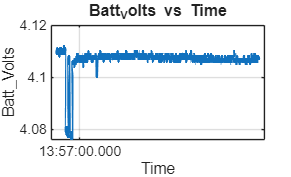

%Plotting
plotSelectedData(FilledTtFlightData, xVarName, yVarName);

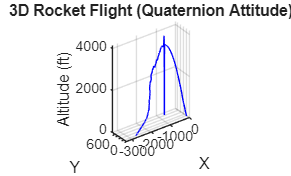

%Flight Animation
animateRocket3D_quat(FilledTtFlightData, z_fused);

%Exporting Data and Figures
exportChoice = menu("Select export option:", ...
    "None", ...
    "Data Only", ...
    "Figures Only", ...
    "Data + Figures");

if exportChoice == 1
    return;
end

%Set the base filename
baseName = input('Enter base filename (no extension): ','s');

%Exporting Data
if exportChoice == 2 || exportChoice == 4

    exportOptions = [ ...
        "Fused Altitude (z_fused)", ...
        "Fused Velocity (v_fused)", ...
        "Fused Acceleration (a_fused)", ...
        "All Fused Data", ...
        "Original Filled Flight Data" ...
    ];

    exportSelection = menu("Select data to export:", exportOptions);

    t = seconds(FilledTtFlightData.Time - FilledTtFlightData.Time(1));
    t = t(:);

    switch exportSelection

        case 1
            T_export = table(t, z_fused, ...
                'VariableNames', {'Time_s','Altitude_ft'});

        case 2
            T_export = table(t, v_fused, ...
                'VariableNames', {'Time_s','Velocity_ft_s'});

        case 3
            T_export = table(t, a_fused, ...
                'VariableNames', {'Time_s','Acceleration_ft_s2'});

        case 4
            T_export = table(t, z_fused, v_fused, a_fused, ...
                'VariableNames', {'Time_s','Altitude_ft','Velocity_ft_s','Acceleration_ft_s2'});

        case 5
            T_export = timetable2table(FilledTtFlightData);
    end

    writetable(T_export, [baseName '.csv']);
    fprintf('Data exported to %s.csv\n', baseName);

end

%Export Figures
if exportChoice == 3 || exportChoice == 4

    figs = findall(0, 'Type', 'figure');

    if isempty(figs)
        fprintf('No figures found to export.\n');
    else
        for k = 1:length(figs)

            fig = figs(k);
            figNum = fig.Number;

            exportgraphics(fig, sprintf('%s_fig%d.png', baseName, figNum));
            savefig(fig, sprintf('%s_fig%d.fig', baseName, figNum));

        end

        fprintf('Exported %d figure(s).\n', length(figs));
    end

end